**Questão 1:**O x é o nosso sinal, fa frequencia de amostragem, já está no nosso sinal.


load Guitar03.mat
%sound(x,fa);
% retorna:
                      % x   ->  sinal
                      % fa  ->  frequencia de amostragem


**Questão 2:**

É difícil identificar uma nota, não é sinusoidal.

Cada risca é uma nota, vemos a frequência e convertemos para uma nota.

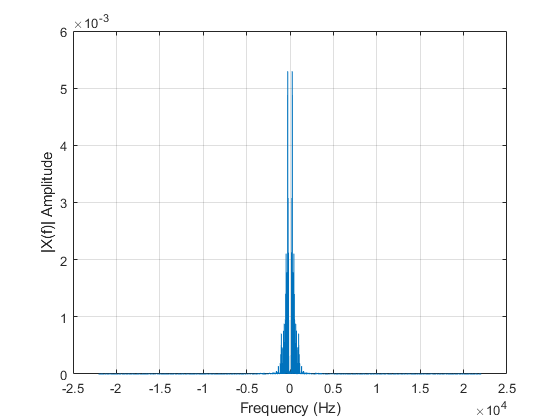


figure(2)
Ta=1/fa;
x=x-mean(x); %retira o valor médio ao x
[X,f]= Espectro(x,Ta,0);

% X -> vetor com os coeficientesda DFT de x(T)
% f -> vetor com as frequencias de cada componente de X


**Questão 3:**

O objetivo é fazer um filtro aplicado sobre o espetro (i.e., um filtro que opera no domínio da frequência), e remova o conteúdo espetral desse sinal que se situe abaixo da frequência 100 Hz e acima da frequência 400Hz e depois repetir os testes para outros valores.

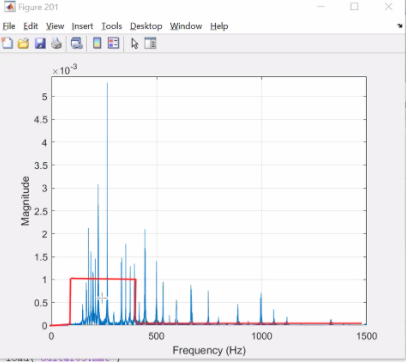

100 com 400, menos robo, mais grave, mas normal

400 e 600 pareceu alien? estranho mas fixe

600 a 1200 totalmente de outro m undo, mais fininho

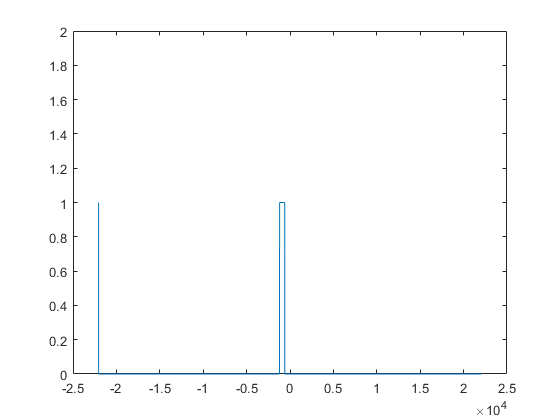

fL=600;
fH=1200;
H=zeros(size(f));
H(f>-fH)=1;
H(f>-fL)=0;
H(fL>0)=1;
H(f>fH)=0;
figure(3);
plot(f,H); %para definir o filtro
ylim([0 2]);

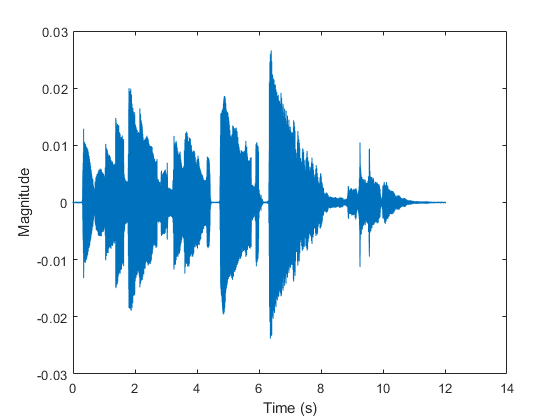


Xf=H.*X; % Espetro do sinal filtrado
% linha onde filtramos o espetro do sinal X  
% (resultado da função Espetro), multiplicar
% ponto a ponto no espetro do X pelo que criei agora,

%Para ouvirmos no domínio do tempo (não conseguimos ouvir a partir do
%espetro), aplicamos a funcao Reconstroi:

[w,tn]= Reconstroi (Xf,f);

w=real(w); %sinal filtrado. 
%Real=não tem imaginario
%Se o espetro tiver ligeiro problema de simetria, 
%a funcao Reconstroi devolve com uma pequena parte imaginaria. 
%Se nao registassemos só a parte real podia dar um erro quando fizessemos
%plot

**Renormalização da potencia do sinal:**

Não convem que a frequencia seja demasiado forte, nada garante que o resultado final do processamento tenha a mesma amplitude sonora, pode ser muito diferente. Devemos ter o cuidado para nao ouvir um som muito estridente, temos de normalizar sempre a amplitude sonora ao mesmo valor.

Aqui entra o conceito de potencia, tenho que garantir que a potencia do sinal processado é igual à do original.

Podíamos utilizar a função potencia tambem.

N=length(x);
Px= x'*x/N; %Potencia do sinal x
Pw=w'*w/N; % Potencia do sinal w
w=w*sqrt(Px/Pw); %maneira de ser o mesmo sinal
%sound(w,fa);


**Questão 4:**

Chave de conseguir bom som: ter** bom processamento**

O efeito Chorus produz a sensação de existirem vários instrumentos a tocar ao mesmo tempo, e é gerado por adição de várias réplicas do sinal atrasadas no tempo de uma determinada quantidade aleatória. 

y=Chorus(x,fa,MaxDelay,NumComp)

x-> sinal original; Max Delay do x; NumComp-> nº de replicas que a função deve fazer.

Atrasos vão ser calculados aleatóriamente.

Conclusões depois de correr:

No início encontramos 0, os atrasos que estamos a introduzir não fazem diferença pq o sinal começa mesmo em 0.

Conclusao dos graficos: as frequencias sao as mesmas, tudo o que muda é a amplitude das riscas que já existiam e as fases de cada uma.

Pq nao aparece frequencias novas? Pq a função chorus, que soma replicas, pq soma e atraso de um sinal são funções lineares. Os operadores lineares nunca mudam a frequencia de um sinal, só influenciam a amplitude.

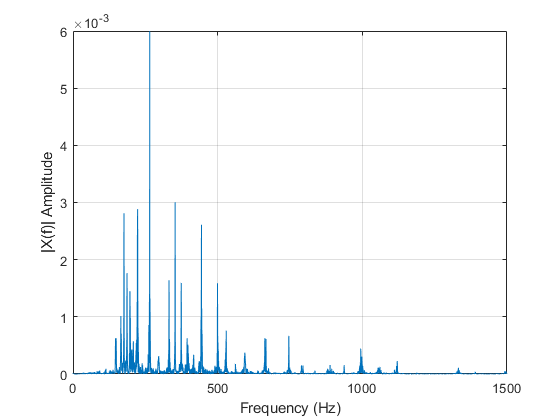

MaxDelay=0.3;
NumComp=5;
y=Chorus(x,fa,MaxDelay, NumComp);
sound(y,fa);
figure(4);
[y,fy]=Espectro(y,Ta,0);
xlim([0 1.5e3]);

**Questão 5: **Estamos adicionar apenas uma replica cujo atraso vai variando ao longo do tempo, variando de uma forma desrelacionada com o sinal. Criamos um som dinâmico. Variar o tom ligeiramente.

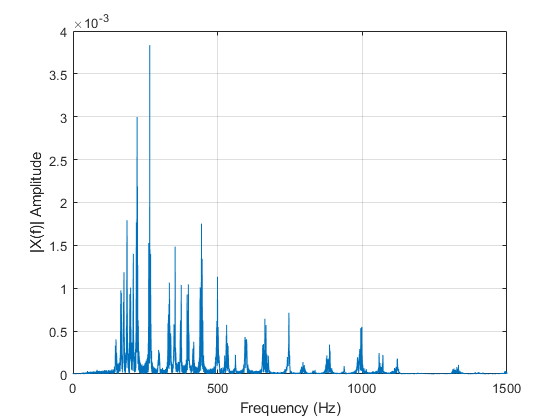

MaxDelay=0.02;
Freq=0.2;
y=Flanger(x,fa,MaxDelay,Freq);
sound(y,fa);
figure(5);
[Y,fy]=Espectro(y,Ta,0);
xlim([0 1500]);

**Questão 6: **Reverb, o som faz com que as "paredes" vibrem, mas como o som viaja vai perdurando, é um som "atrasado". 

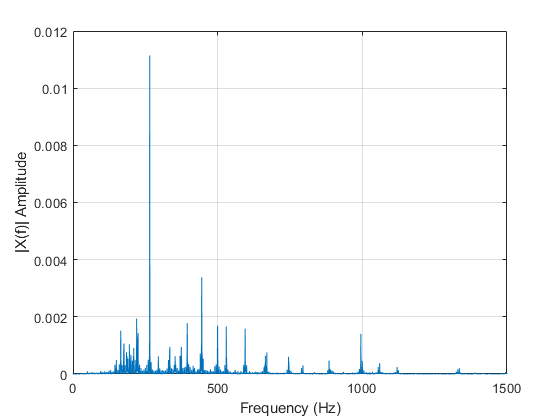

Delay=0.2;
Gain=0.8;
y=Reverb(x,fa,Delay,Gain);
sound(y,fa);
figure(6)
[Y,fy]=Espectro(y,Ta,0);
xlim([0 1.5e3]);

**Questão 7: **muito devagarinhooo

sound(x,fa/2);

**Funções necessárias:**

function [X,f]= Espectro (x,Ta,w)
    N=length(x);
    f0=1/(N*Ta); %periodo = N*Ta
    fa= 1/Ta;
    f=[-fa/2:fa/N:(fa/2-fa/N)]';
    
    %windowing
    if w~=0
        w=blackman(N);
        x=x*w;
        
    end
    
    X=fft(x);
    X=fftshift(X)/N; %vetor com N elementos
    plot( f, abs(X));
    xlabel('Frequency (Hz)');
    ylabel('|X(f)| Amplitude');
    grid;
end


function[x,t]= Reconstroi (X,f,w)
     N=length(X);
     fa=-f(1)*2;
     X = ifftshift(X);
    
     x = real( ifft(X)*N);
 
     fa = f(end)*2;
     Ta = 1/fa;
   
     t = [0: Ta: (N-1)*Ta]';
     plot(t, x);
     xlabel("Time (s)")
     ylabel("Magnitude")
end


function y=Chorus(x,fa,MaxDelay, NumComp)

    N=length(x);
    y=zeros(N,1);

    for n=1:NumComp
        CurDelay= random('Uniform',0,MaxDelay,1,1); %atraso aleatorio
                                 %parametros da distrib. uniforme. 
            %vai devolver um valor entre 0 e Max delay (1x1[]).
            
         %Mas como vamos receber isto em segundos não dá. Temos de converter para amostras:                        
       % dn=max([1 round ay por Ta corresponde ao número de amostras, mas
     %prof fez inverso. Nada obriga que dê um numero inteiro. Os indices de
     %amostras tem de ser sempre inteiros por isso temos de arredondar.
     %A funcao random pode me devolver um atraso de 0, o prof queria
     %garantir que pelo menos deslizasse uma amostra. Se o resultado der 0,
     %irá haver um deslize de 1.
     dn=max( [1 round(CurDelay*fa)]);
     %Atraso efetivo: %explicação caderno
     %basicamente shift de uma unidade
     
     %criar y com replica atrasada
     
        y(dn:end)=y(dn:end)+x(1:end-dn+1);
    %ir sempre somando as novas replicas
    
    end
    Px=x'*x/N;
    Py=y'*y/N;
    y=y*sqrt(Px/Py);
    %Mt importante normalizar aqui, se nao fizessmos o resultante ia ter
    %muito mais potencia que o original.
end


function y=Reverb(x,fa,Delay,Gain)

N=length(x);
y=zeros(N,1); 
D=round(Delay*fa); %transformar o delay de y num numero de amostras (segundos p amostras)
%(Delay)/Ta = , round para int, amostras sempre inteiras

%implementar o diagrama de blocos (caderno)
%percorremos todas as amostras. 
%Vai ser y- (n-D) o que aconteceu de amostras atrasadas. Adicionamos ao y a
%amostra atrasada, confuso ver video min 33.
%Mas pq max? 
for n=1:N
    y(n)=x(n) + Gain*y(max([1 n-D]));
   
end
 Px=x'*x/N;
 Py=y'*y/N;
 y=y*sqrt(Px/Py);
end

function y=Flanger(x,fs,MaxDelay,Freq)

N=length(x);
y=zeros(N,1);

for n=1:N
    dn=round((MaxDelay/2*cos(2*pi*Freq*(n-1)/fs)- MaxDelay/2)*fs);
    y(n)=x(max([1 n+dn]));
    
end
y=x+y;
Px=x'*x/N;
Py=y'*y/N;
y=y*sqrt(Px/Py);
end